soln_analytical = 14 / 3

soln_analytical = 4.6667


a = 0

a = 0

b = 3

b = 3


n = 10

n = 10


dx = (b - a) / n

dx = 0.3000


left_riemann_sum = sum(sqrt((a + ((1:n) - 1) .* dx) + 1) .* dx)

left_riemann_sum = 4.5148


right_riemann_sum = sum(sqrt((a + (1:n) .* dx) + 1) .* dx)

right_riemann_sum = 4.8148

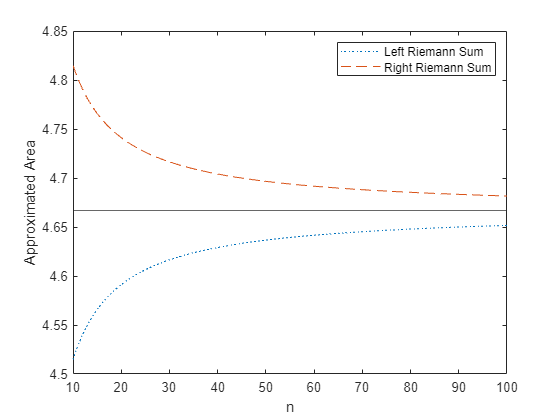


Ln = zeros(1, 90);
Rn = zeros(1, 90);

for m = 10:100
   dx = (b - a) / m;
   left_riemann_sum = sum(sqrt((a + ((1:m) - 1) .* dx) + 1) .* dx);
   Ln(m - 9) = left_riemann_sum;
   right_riemann_sum = sum(sqrt((a + (1:m) .* dx) + 1) .* dx);
   Rn(m - 9) = right_riemann_sum;
end

plot((10:100), Ln, ":")
hold on
plot((10:100), Rn, "--")
yline(soln_analytical)

legend("Left Riemann Sum", "Right Riemann Sum")
ylabel("Approximated Area")
xlabel("n")